# The Friedkin–Johnsen model: theory and simulations of the report

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## Settings

saveEps = false leaves the figures on screen only; set it to true to write the .eps files of Part 2 into outDir. They are never written into FINAL/report/figures.

if ~exist('saveEps','var'), saveEps = false; end
if ~exist('outDir','var'),  outDir = fullfile(projectDir,'livescripts','report_figures'); end
if saveEps && ~isfolder(outDir), mkdir(outDir); end

## Part 1 – Theory (from ch04_fj_v3.mlx, Sections 4.1–4.3)

## Direction convention

Every matrix in this project follows one rule:

Equivalently, row i lists whom agent i listens to, which is why the rows are the objects that must sum to one.

The two books in the repository draw the arrows in opposite directions: Proskurnikov & Tempo point them along the flow of influence, Bullo points them from the advice seeker to the advisor. THE MATRIX IS THE SAME; only the picture differs.

In this live script, Part 1 follows Proskurnikov & Tempo, so a stubborn agent is a source node; the report and Part 2 follow the course convention (an edge i → j means that agent i is influenced by agent j), so the same agent is a sink.

## 4.1 Friedkin-Johnsen model

This model introduced a discrete-time modification of Taylor's model. This model has been experimentally validated for small and medium-size groups.

Similar to DeGroot's dynamics [M1.1](matlab:open('./ch01_fdg.mlx')), the Friedkin-Johnsen model employs a stochastic matrix of social influences $W$, corresponding to the influence graph $\mathcal G[W]$. 

Beside this matrix, a diagonal matrix $\Lambda = diag(\lambda_1, \dots, \lambda_n)$ is introduced, where $\lambda_i \in [0,1]$ stands for the susceptibility of agent $i$ to the process of social influence. 

The vector of the agents' opinion evolves in accordance with 

                                                                            (M4.1)$x(k+1) = \Lambda W x(k) + (I-\Lambda)u$

Here $u$ is a constant vector of the agents' prejudices. 

The susceptibilities' complements $1-\lambda_i$ play the same role as the coefficients $\gamma_i$ in Taylor's model.

- $\Lambda = I$ the model M4.1 turns into the French-DeGroot model [M1.1](matlab:open('./ch01_fdg.mlx'))

- If $1-\lambda_i=0$ then agent $i$ is independent of the prejudice vector $u$ and applies the usual French-DeGroot rule

- When $\lambda_i<1$ agent i is anchored to its prejudice $u_i$ and factors it into any opinion iteration.

- If $\lambda_i =0$ then the $i$-th agents' opinion stabilizes at the first step $x_i(k) \equiv u_i \ \forall k \ge 1$; such an agent is stubborn $x_i(k) \equiv x_i(0)$ when $u_i \equiv x_i(0)$

In the Friedkin-Johnsen theory it is supposed traditionally that $u = x(0)$, ie the prejudices of the agents are their initial opinions. This assumption motivates to adopt the "coupling condition" $1-\lambda_i = w_{ii}$ stating that the levels of agent's anchorage to the initial opinions are determined by their self-confidence weights. At the same time the prejudice may be independent of the initial opinion, for this reason we do not adopt these coupling conditions in this tutorial.

## 4.2 Convergence and stability conditions

We call agent $i$ **prejudiced** if $\lambda_i<1$, ie the prejudice $u_i$ influences its opinion at each step $k$

We split agents in two classes:

- Agent $i$ is said to be **P-dependent **(prejudice dependent, for simplicity **PD**) if is either prejudiced or influenced by some prejudiced agent $j$ (ie: a walk from $j$ to $i$ exists in the graph $\mathcal G [A]$).

- Agent i is said to be **P-independent **(for simplicity **PI**) otherwise.

Assume agents $1, \dots,r\ge 1$ are PD and agents $r+1,\dots,n$ are PI (possibly $r=n$). Denote the corresponding parts of the opinion vector by, respectively, $x_1(t)\in\mathbb R^r$ and $x_2(t)\in\mathbb R^{n-r}$. 

Since PI agents are, by definition, not prejudiced ($\lambda_i = 1$), then  M4.1 is decomposed as

                                                        (M4.1.1)$x_1(k+1) = \Lambda^{11}[W^{11}x_1(k)+W^{12}x_2(k)]+(I-\Lambda^{11})u_1$

                                                                                (M4.1.2)$x_2(k+1) = W^{22}x_2(k)
$

The matrix $W^{22}$ is a stochastic matrix, ie the PI agents obey the French-DeGroot model.

**Theorem 4.1 **Let the community have $r\ge1$ PD agents and $n-r\ge0$ PI ones. Then the subsystem M4.1.1 is asymptotically stable, ie $\Lambda^{11}W^{11}$ is Schur stable $\rho(\Lambda^{11}W^{11})<1$. The model M4.1 is convergent $\iff$ $r=n$ or M4.1.2 is convergent, ie $W^{22}$ is regular. In this case:

                                                                            (E4.1)    $x^1(\infty) = V[u^1, x^2(\infty)]^T \\
V \triangleq (I_r -\Lambda^{11}W^{11})^{-1}[I_r-\Lambda^{11}, \ \Lambda^{11}W^{12}]$

The matrix $V$ is stochastic, ie the final opinion of any agent is a convex combination of the prejudices and final opinions of PI agents.

**Corollary 4.1 **The Friedkin-Johnsen model M4.1 is asymptotically stable $\iff$ all agents are PD. Then $V = (I- \Lambda W)^{-1}(I-\Lambda)$. This holds, in particular, if $\Lambda < I_n$ or $\Lambda \neq I_n$ and $\mathcal G[W]$ is strongly connected ( $W$ is irreducible).

**Corollary 4.2 **The model M4.1 converges $\iff$ $A = \Lambda W$ is regular, ie the limit $\lim_{k \rightarrow \infty}A^k$ exists

## 4.3 Friedkin's influence centrality and PageRank

A natural question arises whether the concept of social power can be extended to model M4.1. Such extension will be based on the equality E4.1. We confine ourselves to the case of asymptotically stable model M4.1 with the prejudice vector $u = x(0)$, hence $x(\infty) = Vx(0)$ where $V = (I - \Lambda W)^{-1}(I-\Lambda)$.

French's social power assumed that the agents converge to the same consensus opinion $x_1(\infty) = \dots = x_n(\infty)$; the social power of agent $i$ is defined as the weight of its initial opinion $x_i(0)$ in this final opinion of the group.

FJ models provides a generalization of social power of agent $i$ as the mean weight of its initial opinion in determining group members' final opinions. Mathematically, these mean influence weights are elements of the non-negative vector $c \triangleq n^{-1}V^T\mathbb 1_n$, which satisfies the following equality

                                                                        (E4.2)$\bar x = \frac1n\sum^n_{i=1} x_i(\infty) = \frac1n \mathbb 1_n^TVx(0) = c^Tx(0)$

We call $c_i$ the *influence centrality *of agent $i$. Since $V$ is stochastic, $c^T \mathbb 1_n=1$. 

Similar to French's social power, the influence centrality is generated by an opinion formation mechanism. Choosing a stochastic matrix $W$, adapted to a given graph $\mathcal G$ with $n$ nodes, and some diagonal matrix $\Lambda$, Friedkin's construction gives a very insightful and broad class of centrality measures. 

For a fixed $W$, let $\Lambda = \alpha I_n$ with $\alpha \in (0,1)$ and consider the corresponding matrix $V_\alpha$ and vector $c_\alpha$. Obviously, $c_0 = n^{-1}\mathbb 1_n$, ie the social power is uniformly distributed between all the agents. As $\alpha \rightarrow 1$, the vector $c_\alpha$ converges to French's social power (when it exists).

**Lemma 4.1 **Let $W$ be a fully regular matrix and $p_\infty$ stand for the vector of French's social power, corresponding to the model  [M1.1](matlab:open('./ch01_fdg.mlx')). Then $p_\infty = \lim_{\alpha \rightarrow 1-0}c_\alpha$

Indeed $V_\alpha = (1-\alpha)(I-\alpha W)^{-1}\rightarrow W^\infty$ for $\alpha \rightarrow 1^-$, where $W^\infty = \lim_{k \rightarrow \infty}W^k = \mathbb 1_np^T$. Thus $c_\alpha = n^{-1}V_\alpha^T\mathbb 1_n \rightarrow p_\infty$ for $\alpha \rightarrow 1^-$.

## Part 2 – Simulations of the report (Section 3.2)

Theorem 4.1 (Part 1) = Theorem 3.2 (report) = Theorem 21 in [5]

Corollary 4.1 (Part 1) = Corollary 3.3 (report) = Corollary 22 in [5]

Corollary 4.2 (Part 1) = Corollary 3.4 (report) = Corollary 23 in [5]

Lemma 4.1 (Part 1) = Lemma 3.5 (report) = Lemma 24 in [5]

% Common parameters of Section 3.2 of the report: the two networks of Figure 1 on
% n = 6 agents (no self-loops), the initial opinions, and one colour per agent kept
% the same in every figure. Cleared first, so nothing from Part 1 leaks in.
clearvars -except saveEps outDir projectDir

n  = 6;
x0 = [0; 0.2; 0.4; 0.6; 0.8; 1];
Wcyc  = rep_cycle_matrix(n);       % directed cycle:     w_{i,i+1} = 1
Wring = rep_ring_matrix(n);        % bidirectional ring: w_{i,i-1} = w_{i,i+1} = 1/2
nets  = {'directed cycle', Wcyc; 'bidirectional ring', Wring};

% same colour per agent in every figure; agent 1 is black and marked with dots
agentColour = lines(n);
agentColour(1,:) = [0 0 0];

pass  = true;                      % set to false by the first check that fails
tol   = 1e-3;                      % tolerance of the numerical checks

## Figure 6 – Modelling stubbornness: prejudices and stubborn agents

Report: Section 3.2.1, paragraph «The stubborn agent as an input», Figure 6 (FINAL/report/figures/fj_stubborn_equivalence.eps).

Caption in the report:

Opinions $x_i(k)$ in the FDG model with $A(1)$ (left) and in the FJ model with $\lambda _1 = 0$, $\lambda _i = 1$ for $i \neq 1$ and $u = x(0)$ (right), on the directed cycle ($K = 10$, top) and on the bidirectional ring ($K = 40$, bottom), with $x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $. Agent $1$ is black and marked with dots.

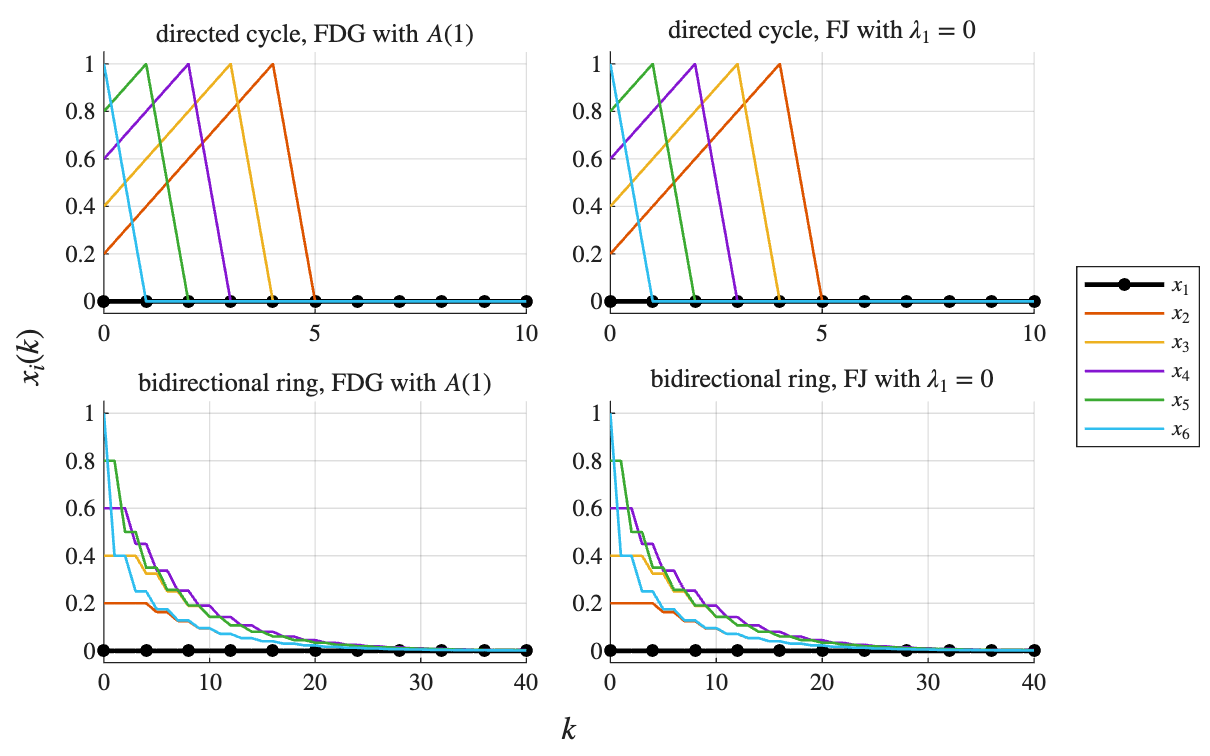

% Report Figure 6. The stubborn agent as an input. Left: the FDG model (1) with A(1)
% of (3), where agent 1 keeps its own opinion as a state. Right: the FJ model (4) with
% lambda_1 = 0, lambda_i = 1 otherwise and u = x(0), where that opinion is the input
% u_1. The two produce the same trajectories, which is what the check below measures.
% Panels: rows are the networks, directed cycle (K = 10) on top, bidirectional ring
% (K = 40) below.
Ks = [10, 40];                                  % cycle, ring
lamStub = [0; ones(n-1,1)];                     % lambda_1 = 0, lambda_i = 1
fig = rep_new_figure(16, 10);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
d1  = 0;
for r = 1:2
    W = nets{r,2};  K = Ks(r);
    Xf = rep_sim_fdg(rep_self_weight(W, 1), x0, K);     % FDG, agent 1 stubborn
    Xj = rep_sim_fj(W, lamStub, x0, x0, K);         % FJ, lambda_1 = 0, u = x(0)
    d1 = max(d1, max(abs(Xf - Xj), [], 'all'));
    for col = 1:2
        ax = nexttile(tl);
        if col == 1, X = Xf; ttl = sprintf('%s, FDG with $A(1)$', nets{r,1});
        else,        X = Xj; ttl = sprintf('%s, FJ with $\\lambda_1 = 0$', nets{r,1});
        end
        rep_draw_traj(ax, X, K, agentColour, n);
        title(ax, ttl, 'Interpreter', 'latex', 'FontWeight', 'normal');
        ylim(ax, [-0.05, 1.05]);
    end
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
rep_shared_legend(tl, ax, agentColour, n);

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_stubborn_equivalence.eps'));
end
% Check 1 of make_fj_figures.m: the two models of the figure agree to machine zero.
fprintf('%s\n', sprintf('1. max |x_FDG - x_FJ| over both networks : %.3e', d1));

1. max |x_FDG - x_FJ| over both networks : 0.000e+00


pass = rep_check(pass, d1 < 1e-12, '     MISMATCH, expected below 1e-12');

## Figure 7 – Modelling stubbornness: prejudices and stubborn agents

Report: Section 3.2.1, paragraph «State or input», Figure 7 (FINAL/report/figures/fj_stubborn_perturbation.eps).

Caption in the report:

The models of Figure 6 started from $x_1(0) = 0.5$, with the other initial opinions and the prejudice vector $u = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $ unchanged, so $u_1 \neq x_1(0)$. Left: FDG with $A(1)$; right: FJ with $\lambda _1 = 0$. Top: directed cycle, $K = 10$; bottom: bidirectional ring, $K = 40$.

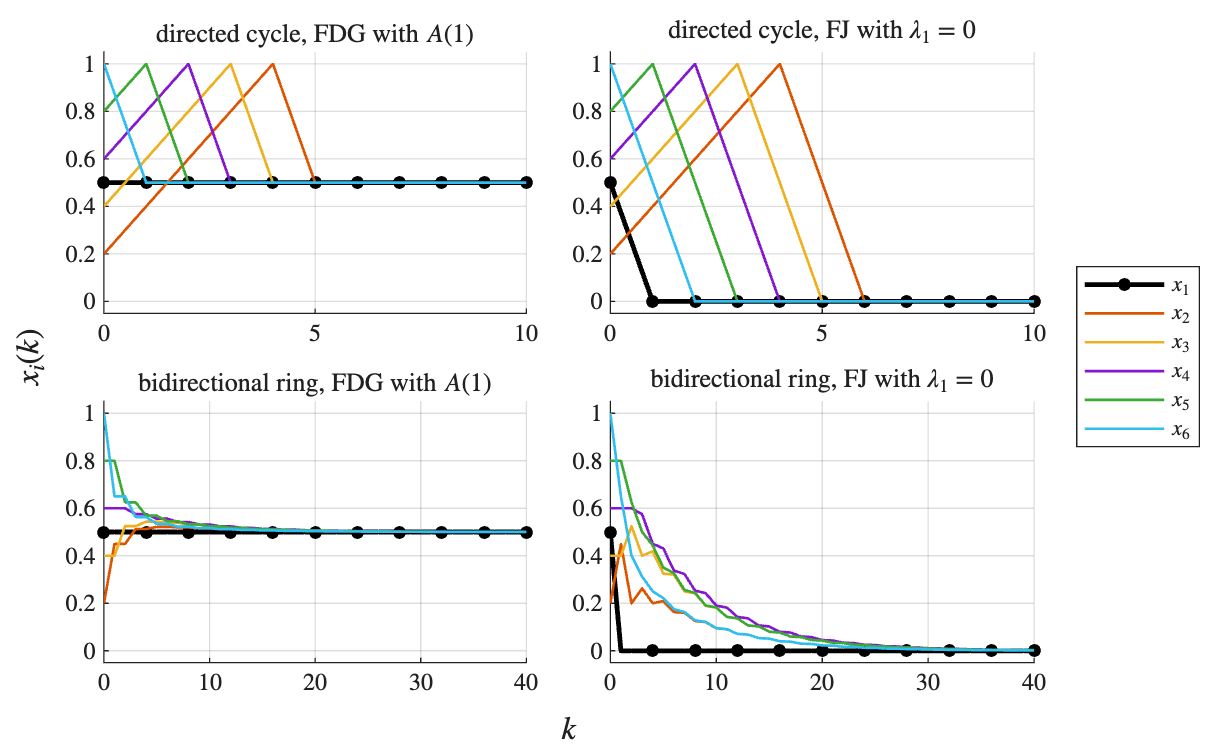

% Report Figure 7. State or input. The same two models started from x_1(0) = 0.5 while
% the prejudice vector stays u = (0, 0.2, 0.4, 0.6, 0.8, 1)', so u_1 differs from
% x_1(0). In the FDG model agent 1 is a state and the group follows it to 0.5; in the
% FJ model (4) the group still converges to u_1 = 0, because the input did not move.
% Panels: rows are the networks, left FDG with A(1), right FJ with lambda_1 = 0.
x0p = x0;  x0p(1) = 0.5;                        % u is left unchanged: u_1 = 0
fig = rep_new_figure(16, 10);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
Xp  = cell(2,2);
for r = 1:2
    W = nets{r,2};  K = Ks(r);
    Xp{r,1} = rep_sim_fdg(rep_self_weight(W, 1), x0p, K);
    Xp{r,2} = rep_sim_fj(W, lamStub, x0, x0p, K);
    for col = 1:2
        ax = nexttile(tl);
        if col == 1, ttl = sprintf('%s, FDG with $A(1)$', nets{r,1});
        else,        ttl = sprintf('%s, FJ with $\\lambda_1 = 0$', nets{r,1});
        end
        rep_draw_traj(ax, Xp{r,col}, K, agentColour, n);
        title(ax, ttl, 'Interpreter', 'latex', 'FontWeight', 'normal');
        ylim(ax, [-0.05, 1.05]);
    end
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
rep_shared_legend(tl, ax, agentColour, n);

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_stubborn_perturbation.eps'));
end
% Check 2 of make_fj_figures.m: the two limits of the figure, 0.5 for the FDG model
% and 0 for the FJ one, on both networks.
for r = 1:2
    Lf = rep_sim_fdg(rep_self_weight(nets{r,2}, 1), x0p, 2000);
    Lj = rep_sim_fj(nets{r,2}, lamStub, x0, x0p, 2000);
    df = max(abs(Lf(:,end) - 0.5));
    dj = max(abs(Lj(:,end) - 0));
    fprintf('%s\n', sprintf('2. %-19s FDG limit vs 0.5*1_6 : %.3e | FJ limit vs 0 : %.3e', ...
        nets{r,1}, df, dj));
    pass = rep_check(pass, df < tol && dj < tol, '     MISMATCH, expected below 1e-3');
end

2. directed cycle      FDG limit vs 0.5*1_6 : 0.000e+00 | FJ limit vs 0 : 0.000e+00
2. bidirectional ring  FDG limit vs 0.5*1_6 : 2.220e-16 | FJ limit vs 0 : 9.212e-126


## Figure 9 – Prejudices, stubbornness and convergence

Report: Section 3.2.2, paragraph «A single prejudice», Figure 9 (FINAL/report/figures/fj_one_prejudiced.eps).

Caption in the report:

Opinions $x_i(k)$ with the same weight $1/2$ on agent $1$, with $x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $ and $K = 60$. Left: FDG model with self-weight $t = 1/2$ (matrix $A(1/2)$, current opinion); right: FJ model with $\lambda _1 = 1/2$, $\lambda _i = 1$ for $i \neq 1$ and $u = x(0)$ (attachment $1 - \lambda _1 = 1/2$, initial opinion). Top: directed cycle; bottom: bidirectional ring. The triangles mark the limits: the consensus value $\approx 0.4286$ of the FDG model and $u_1 = 0$ for the FJ model.

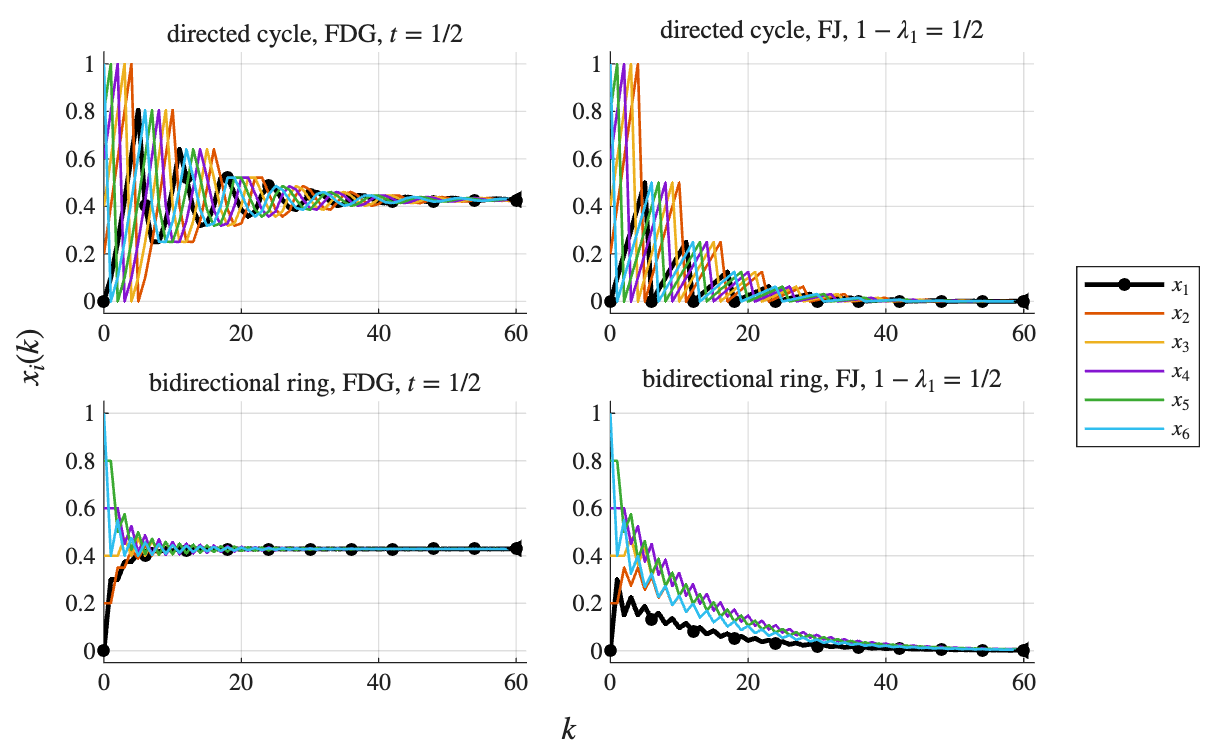

% Report Figure 9. A single prejudice, with the same weight 1/2 on agent 1 in the two
% models. Left: the FDG model (1) with A(1/2) of (3), where the weight goes to the
% current opinion x_1(k). Right: the FJ model (4) with lambda_1 = 1/2, where it goes to
% the prejudice u_1 = x_1(0). The triangles mark the limits: the FDG consensus
% w(1/2)' x(0) = 0.4286 and the FJ limit u_1 = 0.
% Panels: rows are the networks, left FDG, right FJ.
Kp  = 60;
aFDG = rep_social_power(rep_self_weight(Wcyc, 0.5)).' * x0;     % FDG consensus at t = 1/2
fig = rep_new_figure(16, 10);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
steps = zeros(1,2);
Afdg2 = cell(2,1);                              % A(1/2), kept for the checks
for r = 1:2
    W = nets{r,2};
    % left: the FDG model, the weight 1/2 going to the CURRENT opinion x_1(k)
    A  = rep_self_weight(W, 0.5);  Afdg2{r} = A;
    Xf = rep_sim_fdg(A, x0, Kp);
    ax = nexttile(tl);
    rep_draw_traj(ax, Xf, Kp, agentColour, n);
    hold(ax, 'on');
    plot(ax, Kp, rep_social_power(A).' * x0, '<', 'Color', [0 0 0], ...
        'MarkerFaceColor', [0 0 0], 'MarkerSize', 5, 'HandleVisibility', 'off');
    hold(ax, 'off');
    xlim(ax, [0, Kp + 1.5]);
    ylim(ax, [-0.05, 1.05]);
    title(ax, sprintf('%s, FDG, $t = 1/2$', nets{r,1}), ...
        'Interpreter', 'latex', 'FontWeight', 'normal');
    % right: the FJ model, the same weight going to the INITIAL opinion u_1 = x_1(0)
    lam = ones(n,1);  lam(1) = 0.5;             % attachment 1 - lambda_1 = 1/2
    X   = rep_sim_fj(W, lam, x0, x0, Kp);
    Xl  = rep_sim_fj(W, lam, x0, x0, 400);
    kk  = find(max(abs(Xl), [], 1) < tol, 1) - 1;
    if isempty(kk), kk = NaN; end
    steps(r) = kk;
    ax = nexttile(tl);
    rep_draw_traj(ax, X, Kp, agentColour, n);
    hold(ax, 'on');
    plot(ax, Kp, 0, '<', 'Color', [0 0 0], 'MarkerFaceColor', [0 0 0], ...
        'MarkerSize', 5, 'HandleVisibility', 'off');     % the limit is u_1 = 0
    hold(ax, 'off');
    xlim(ax, [0, Kp + 1.5]);
    ylim(ax, [-0.05, 1.05]);
    title(ax, sprintf('%s, FJ, $1-\\lambda_1 = 1/2$', nets{r,1}), ...
        'Interpreter', 'latex', 'FontWeight', 'normal');
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
rep_shared_legend(tl, ax, agentColour, n);

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_one_prejudiced.eps'));
end
% Check 4 of make_fj_figures.m: the social power w(1/2) and the consensus value behind
% the left column, the FJ limit and the number of steps to reach it behind the right
% column, and how close the FDG column is to 3/7 at k = 60.
for r = 1:2
    w = rep_social_power(rep_self_weight(nets{r,2}, 0.5));
    dw = max(abs(w - [2/7; repmat(1/7, n-1, 1)]));
    fprintf('%s\n', sprintf('4. %-19s w(1/2) = [%s]  (max dev %.3e)', nets{r,1}, ...
        strjoin(compose('%.4f', w.'), ' '), dw));
    pass = rep_check(pass, dw < tol, '     MISMATCH, expected (0.2857, 0.1429 x5)');
end

4. directed cycle      w(1/2) = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]  (max dev 1.943e-16)
4. bidirectional ring  w(1/2) = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]  (max dev 1.110e-16)


fprintf('%s\n', sprintf('4. FDG consensus value at t = 1/2 : %.4f  (expected 0.4286)', aFDG));

4. FDG consensus value at t = 1/2 : 0.4286  (expected 0.4286)


pass = rep_check(pass, abs(aFDG - 3/7) < tol, '     MISMATCH, expected 0.4286');
for r = 1:2
    lam = ones(n,1); lam(1) = 0.5;
    xi = rep_fj_limit(nets{r,2}, lam, x0);
    fprintf('%s\n', sprintf('4. %-19s FJ limit (middle column) : max |x(inf)| = %.3e | steps to 1e-3 : %d', ...
        nets{r,1}, max(abs(xi)), steps(r)));
    pass = rep_check(pass, max(abs(xi)) < tol, '     MISMATCH, expected limit 0');
end

4. directed cycle      FJ limit (middle column) : max |x(inf)| = 0.000e+00 | steps to 1e-3 : 59
4. bidirectional ring  FJ limit (middle column) : max |x(inf)| = 0.000e+00 | steps to 1e-3 : 83


pass = rep_check(pass, steps(1) == 59, '     MISMATCH, expected 59 steps on the directed cycle');
pass = rep_check(pass, steps(2) == 83, '     MISMATCH, expected 83 steps on the bidirectional ring');
for r = 1:2
    Xf = rep_sim_fdg(Afdg2{r}, x0, Kp);
    d60 = max(abs(Xf(:,end) - 3/7));
    fprintf('%s\n', sprintf('4. %-19s FDG, max |x_i(%d) - 3/7| = %.4f', nets{r,1}, Kp, d60));
    pass = rep_check(pass, d60 < 0.01, '     MISMATCH, expected within 0.01 of 0.4286 at k = 60');
end

4. directed cycle      FDG, max |x_i(60) - 3/7| = 0.0038
4. bidirectional ring  FDG, max |x_i(60) - 3/7| = 0.0001


## Figure 10 – Prejudices, stubbornness and convergence

Report: Section 3.2.2, paragraph «Every agent prejudiced», Figure 10 (FINAL/report/figures/fj_all_prejudiced.eps).

Caption in the report:

Opinions $x_i(k)$ when every agent gives weight $0.2$ to its own opinion, with $x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $ and $K = 50$. Left: FDG model with $A = 0.2\, I + 0.8\, W$ (self-weight $a_{ii} = 0.2$, current opinion); right: FJ model with $\Lambda = 0.8\, I$ and $u = x(0)$ (attachment $1 - \lambda _i = 0.2$, initial opinion). Top: directed cycle; bottom: bidirectional ring. The triangles mark the limits: the average $0.5$ of the initial opinions for the FDG model, and $Vu$ of (9) for the FJ model.

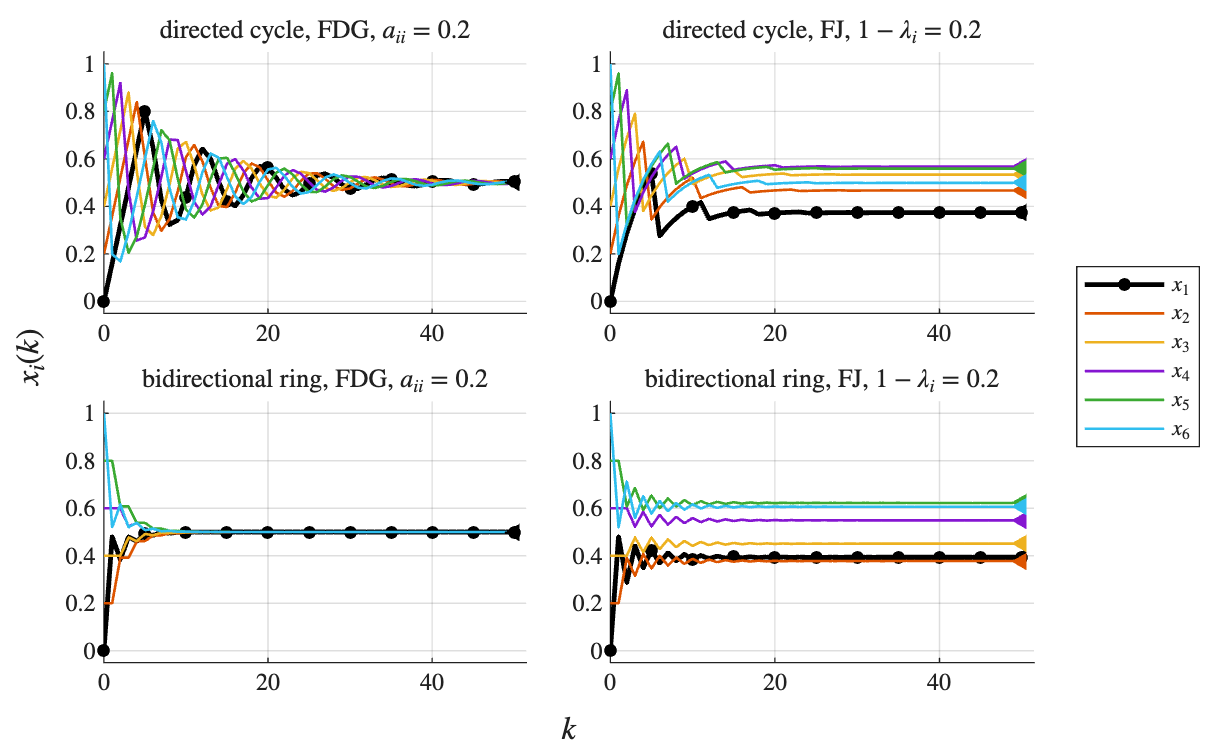

% Report Figure 10. Every agent prejudiced, with the same weight 0.2. Left: the FDG
% model (1) with A = 0.2 I + 0.8 W, the weight going to the current opinion. Right: the
% FJ model (4) with Lambda = 0.8 I and u = x(0), the weight going to the initial one.
% The triangles mark the limits: the average 0.5 of x(0) for the FDG model, and the
% components of V u of (9), with V = (I - Lambda W)^{-1} (I - Lambda), for the FJ one.
% Panels: rows are the networks, left FDG, right FJ.
lamAll = 0.8 * ones(n,1);                       % attachment 1 - lambda_i = 0.2
Ka = 50;
fig = rep_new_figure(16, 10);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
Afdg = cell(2,1);                               % A = 0.2 I + 0.8 W, kept for the checks
for r = 1:2
    W = nets{r,2};
    % left: the FDG model, the weight 0.2 going to the CURRENT opinion x_i(k)
    A  = 0.2 * eye(n) + 0.8 * W;  Afdg{r} = A;
    Xf = rep_sim_fdg(A, x0, Ka);
    ax = nexttile(tl);
    rep_draw_traj(ax, Xf, Ka, agentColour, n);
    hold(ax, 'on');
    plot(ax, Ka, mean(x0), '<', 'Color', [0 0 0], 'MarkerFaceColor', [0 0 0], ...
        'MarkerSize', 5, 'HandleVisibility', 'off');     % the average, one limit for all
    hold(ax, 'off');
    xlim(ax, [0, Ka + 1.5]);
    ylim(ax, [-0.05, 1.05]);
    title(ax, sprintf('%s, FDG, $a_{ii} = 0.2$', nets{r,1}), ...
        'Interpreter', 'latex', 'FontWeight', 'normal');
    % right: the FJ model, the same weight going to the INITIAL opinion u_i = x_i(0)
    X  = rep_sim_fj(W, lamAll, x0, x0, Ka);
    xi = rep_fj_limit(W, lamAll, x0);
    ax = nexttile(tl);
    rep_draw_traj(ax, X, Ka, agentColour, n);
    hold(ax, 'on');
    for i = 1:n
        plot(ax, Ka, xi(i), '<', 'Color', agentColour(i,:), ...
            'MarkerFaceColor', agentColour(i,:), 'MarkerSize', 5, ...
            'HandleVisibility', 'off');
    end
    hold(ax, 'off');
    xlim(ax, [0, Ka + 1.5]);
    ylim(ax, [-0.05, 1.05]);
    title(ax, sprintf('%s, FJ, $1-\\lambda_i = 0.2$', nets{r,1}), ...
        'Interpreter', 'latex', 'FontWeight', 'normal');
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
rep_shared_legend(tl, ax, agentColour, n);

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_all_prejudiced.eps'));
end
% Check 5 of make_fj_figures.m: the matrix V of (9) behind the right column, its first
% row and the fact that it is row-stochastic, and, for the left column, that A is
% doubly-stochastic and its trajectories reach the average 0.5.
expVu = {[0.374;0.467;0.534;0.567;0.559;0.499], [0.394;0.378;0.451;0.549;0.622;0.606]};
expV1 = {[0.271 0.217 0.173 0.139 0.111 0.089], [0.344 0.180 0.106 0.085 0.106 0.180]};
for r = 1:2
    V  = rep_Vmat(nets{r,2}, lamAll);
    xi = V * x0;
    dv = max(abs(xi - expVu{r}));
    dr = max(abs(V(1,:) - expV1{r}));
    ds = max(abs(sum(V,2) - 1));
    fprintf('%s\n', sprintf('5. %-19s V u = [%s]  (dev %.3e)', nets{r,1}, ...
        strjoin(compose('%.3f', xi.'), ' '), dv));
    fprintf('%s\n', sprintf('5. %-19s row 1 of V = [%s]  (dev %.3e) | rows sum to 1 : %.2e', ...
        nets{r,1}, strjoin(compose('%.3f', V(1,:)), ' '), dr, ds));
    pass = rep_check(pass, dv < tol && dr < tol && ds < 1e-12, '     MISMATCH');
end

5. directed cycle      V u = [0.374 0.467 0.534 0.567 0.559 0.499]  (dev 3.336e-04)


5. directed cycle      row 1 of V = [0.271 0.217 0.173 0.139 0.111 0.089]  (dev 4.756e-04) | rows sum to 1 : 4.44e-16


5. bidirectional ring  V u = [0.394 0.378 0.451 0.549 0.622 0.606]  (dev 3.492e-04)


5. bidirectional ring  row 1 of V = [0.344 0.180 0.106 0.085 0.106 0.180]  (dev 3.439e-04) | rows sum to 1 : 2.22e-16


for r = 1:2
    A  = Afdg{r};
    dA = max(max(abs(sum(A,2) - 1)), max(abs(sum(A,1) - 1)));
    Xf = rep_sim_fdg(A, x0, Ka);
    d50 = max(abs(Xf(:,end) - mean(x0)));
    XfL = rep_sim_fdg(A, x0, 4000);
    dinf = max(abs(XfL(:,end) - mean(x0)));
    fprintf('%s\n', sprintf('5. %-19s A doubly-stochastic : %.2e | max |x_i(%d) - 0.5| = %.4f | A^4000 x0 vs 0.5 : %.3e', ...
        nets{r,1}, dA, Ka, d50, dinf));
    pass = rep_check(pass, dA < 1e-12, '     MISMATCH, A is not doubly-stochastic');
    pass = rep_check(pass, d50 < 0.02, '     MISMATCH, expected within 0.02 of 0.5 at k = 50');
    pass = rep_check(pass, dinf < 1e-9, '     MISMATCH, expected A^4000 x0 = 0.5 within 1e-9');
end

5. directed cycle      A doubly-stochastic : 0.00e+00 | max |x_i(50) - 0.5| = 0.0051 | A^4000 x0 vs 0.5 : 1.144e-14
5. bidirectional ring  A doubly-stochastic : 0.00e+00 | max |x_i(50) - 0.5| = 0.0000 | A^4000 x0 vs 0.5 : 2.109e-15


## Figure 12 – Prejudices, stubbornness and convergence

Report: Section 3.2.2, paragraph «Where the prejudice does not arrive», Figure 12 (FINAL/report/figures/fj_auxiliary.eps).

Caption in the report:

Opinions $x_i(k)$ in the FJ model on the auxiliary network of Figure 11, with $u = (0,\, 0.5,\, 1,\, 0.2,\, 0.9,\, 0.6)^\top $, $K = 40$, the prejudiced agent having $\lambda = 0.5$ and every other agent $\lambda _i = 1$. (a) $W_{\mathrm {p}}$, agent $2$ prejudiced; (b) $W_{\mathrm {p}}$, agent $5$ prejudiced; (c) $W_{\mathrm {a}}$, agent $5$ prejudiced. In (a)–(c) $x(0) = u$; (d) as (c) with $x_2(0) = 1$ and $u$ unchanged.

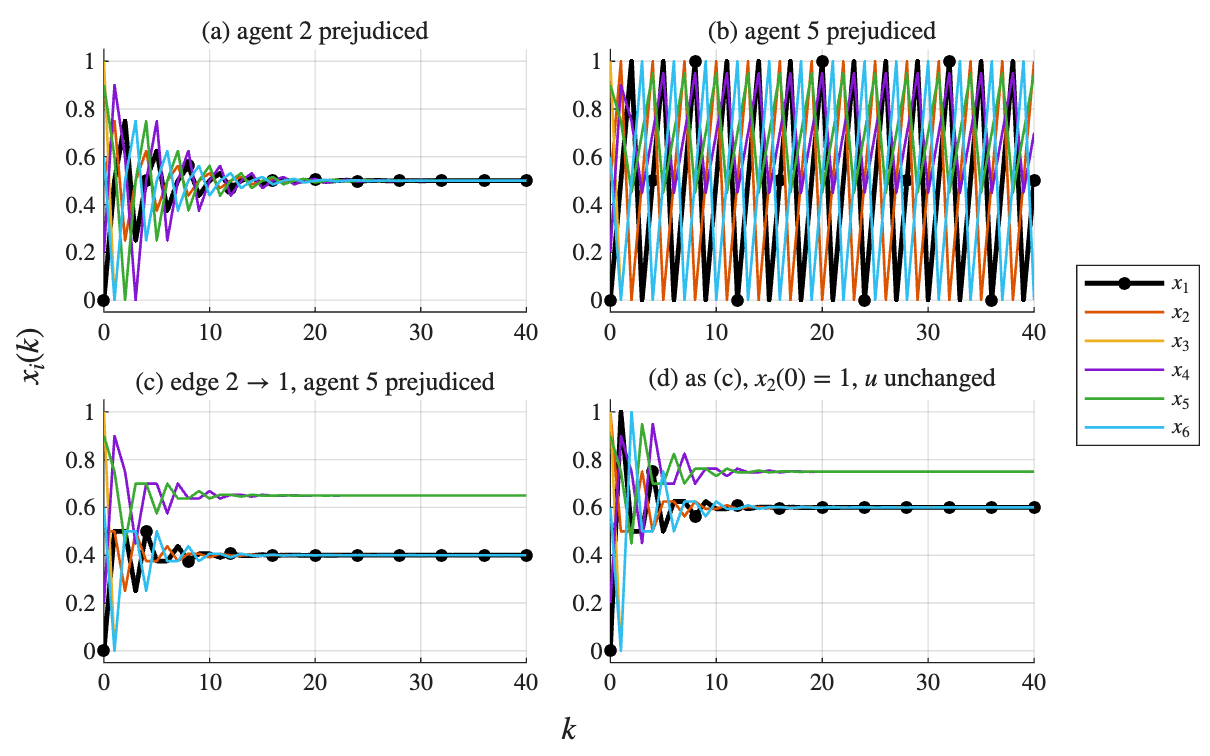

% Report Figure 12. Where the prejudice does not arrive. The FJ model (4) on the
% auxiliary network of report Figure 11, whose agents 1, 2 and 3 form a closed group:
% Wa is the periodic version W_p, Wb the aperiodic version W_a, with the edge 2 -> 1.
% Only the agents joined by a walk to the prejudiced one are P-dependent; the others
% follow an FDG model with the block W^22 of the decomposition (6)-(7).
% Panels: (a) W_p, agent 2 prejudiced; (b) W_p, agent 5 prejudiced; (c) W_a, agent 5
% prejudiced; (d) as (c) with x_2(0) = 1 and u unchanged.
Wa = zeros(n);
Wa(1,2) = 1; Wa(2,3) = 1; Wa(3,1) = 1;          % 1 -> 2 -> 3 -> 1
Wa(4,5) = 1; Wa(5,6) = 1; Wa(6,1) = 1;          % 4 -> 5 -> 6 -> 1
Wb = Wa;  Wb(2,:) = 0;  Wb(2,3) = 0.5;  Wb(2,1) = 0.5;   % extra edge 2 -> 1
x0a = [0; 0.5; 1; 0.2; 0.9; 0.6];
x0d = x0a;  x0d(2) = 1;
Kx  = 40;
% columns: title, W, prejudiced agent, x(0), u
cases = { '(a) agent 2 prejudiced',              Wa, 2, x0a, x0a; ...
          '(b) agent 5 prejudiced',              Wa, 5, x0a, x0a; ...
          '(c) edge $2 \to 1$, agent 5 prejudiced', Wb, 5, x0a, x0a; ...
          '(d) as (c), $x_2(0) = 1$, $u$ unchanged', Wb, 5, x0d, x0a };
fig = rep_new_figure(16, 10);
tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for q = 1:4
    W = cases{q,2};  p = cases{q,3};  xs = cases{q,4};  us = cases{q,5};
    lam = ones(n,1);  lam(p) = 0.5;
    X   = rep_sim_fj(W, lam, us, xs, Kx);
    ax  = nexttile(tl);
    rep_draw_traj(ax, X, Kx, agentColour, n);
    title(ax, cases{q,1}, 'Interpreter', 'latex', 'FontWeight', 'normal');
    ylim(ax, [-0.05, 1.05]);
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
rep_shared_legend(tl, ax, agentColour, n);

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_auxiliary.eps'));
end
% Check 6 of make_fj_figures.m: the limit of each panel, and, for (b), that
% rho(Lambda W) = 1 and the model does not converge at all.
expLim = {0.5*ones(n,1), [], [0.4;0.4;0.4;0.65;0.65;0.4], [0.6;0.6;0.6;0.75;0.75;0.6]};
for q = 1:4
    W = cases{q,2};  p = cases{q,3};  xs = cases{q,4};  us = cases{q,5};
    lam = ones(n,1);  lam(p) = 0.5;
    rho = max(abs(eig(diag(lam)*W)));
    XL  = rep_sim_fj(W, lam, us, xs, 4000);
    conv = max(abs(XL(:,end) - XL(:,end-1))) < 1e-10;
    if isempty(expLim{q})
        fprintf('%s\n', sprintf('6. %-38s rho(Lambda W) = %.4f | converges : %d', ...
            rep_strip_tex(cases{q,1}), rho, conv));
        pass = rep_check(pass, abs(rho - 1) < 1e-10 && ~conv, ...
            '     MISMATCH, expected rho = 1 and no convergence');
    else
        dl = max(abs(XL(:,end) - expLim{q}));
        fprintf('%s\n', sprintf('6. %-38s limit = [%s]  (dev %.3e)', ...
            rep_strip_tex(cases{q,1}), strjoin(compose('%.3f', XL(:,end).'), ' '), dl));
        pass = rep_check(pass, dl < tol, '     MISMATCH');
    end
end

6. (a) agent 2 prejudiced                 limit = [0.500 0.500 0.500 0.500 0.500 0.500]  (dev 0.000e+00)


6. (b) agent 5 prejudiced                 rho(Lambda W) = 1.0000 | converges : 0


6. (c) edge 2 -> 1, agent 5 prejudiced    limit = [0.400 0.400 0.400 0.650 0.650 0.400]  (dev 0.000e+00)
6. (d) as (c), x_2(0) = 1, u unchanged    limit = [0.600 0.600 0.600 0.750 0.750 0.600]  (dev 1.110e-16)


## Figure 13 – Prejudices, stubbornness and influence centrality

Report: Section 3.2.3, paragraph «Where the two measures meet», Figure 13 (FINAL/report/figures/fj_lemma24.eps).

Caption in the report:

Influence centrality $c_1$ and $c_2$ in the FJ model with $W = A(1/2)$ and $\Lambda = \alpha I$, $\alpha \in [0, 0.995]$, and $u = x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $, on the directed cycle (dots) and on the bidirectional ring (crosses). The dashed lines mark the social power $w_1$ and $w_2$ of the FDG model with the same matrix $A(1/2)$, the dotted line the uniform value $1/6$.

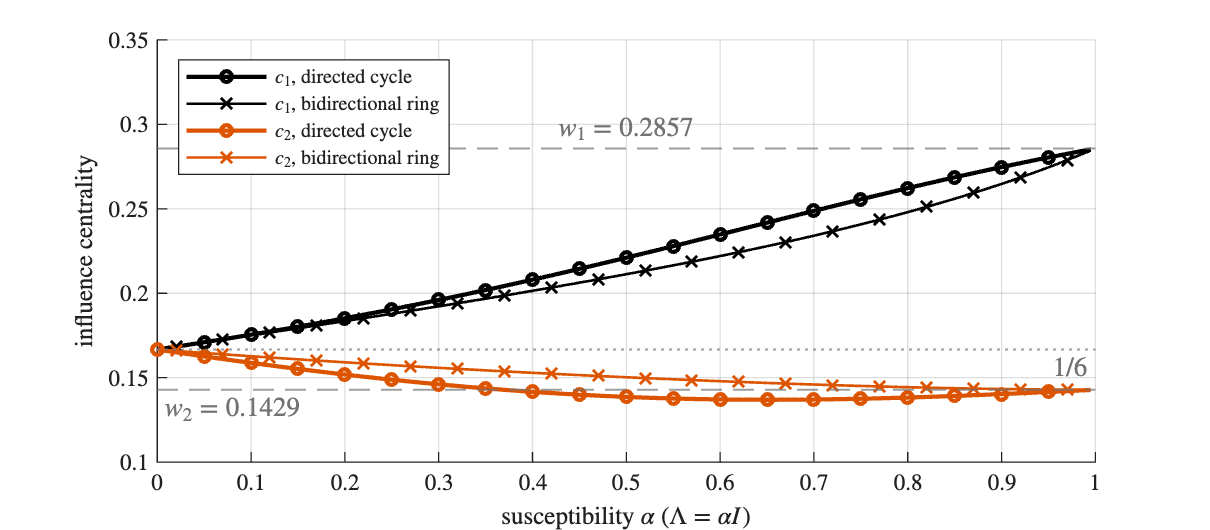

% Report Figure 13. Where the two measures meet. The influence centrality c of (12),
% c = V' 1 / n, computed for W = A(1/2) and Lambda = alpha I as alpha runs over
% [0, 0.995]. Lemma 3.5 of the report says c tends to the FDG social power w of (2):
% the dashed lines mark w_1 and w_2 of the same matrix A(1/2), the dotted line the
% uniform value 1/6 that c takes at alpha = 0.
% One panel: c_1 and c_2, dots on the directed cycle, crosses on the bidirectional ring.
al = 0:0.005:0.995;
Cl = zeros(4, numel(al));                       % c1 cyc, c2 cyc, c1 ring, c2 ring
Wh = {rep_self_weight(Wcyc, 0.5), rep_self_weight(Wring, 0.5)};
for j = 1:numel(al)
    for r = 1:2
        c = rep_centrality(Wh{r}, al(j)*ones(n,1));
        Cl(2*r-1, j) = c(1);  Cl(2*r, j) = c(2);
    end
end
wh = rep_social_power(Wh{1});
fig = rep_new_figure(16, 7);
ax  = axes(fig); hold(ax, 'on');
mkA = 1:10:numel(al);  mkB = 5:10:numel(al);
ref = yline(ax, wh(1), '--', '$w_1 = 0.2857$', 'Color', [0.45 0.45 0.45], ...
    'LineWidth', 0.75, 'Interpreter', 'latex', ...
    'LabelHorizontalAlignment', 'center', 'LabelVerticalAlignment', 'top');
ref.Annotation.LegendInformation.IconDisplayStyle = 'off';
ref = yline(ax, wh(2), '--', '$w_2 = 0.1429$', 'Color', [0.45 0.45 0.45], ...
    'LineWidth', 0.75, 'Interpreter', 'latex', ...
    'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom');
ref.Annotation.LegendInformation.IconDisplayStyle = 'off';
ref = yline(ax, 1/n, ':', '$1/6$', 'Color', [0.45 0.45 0.45], ...
    'LineWidth', 0.75, 'Interpreter', 'latex', ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'bottom');
ref.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(ax, al, Cl(1,:), '-o', 'Color', agentColour(1,:), 'LineWidth', 1.6, ...
    'MarkerSize', 4, 'MarkerIndices', mkA, 'DisplayName', '$c_1$, directed cycle');
plot(ax, al, Cl(3,:), '-x', 'Color', agentColour(1,:), 'LineWidth', 1.0, ...
    'MarkerSize', 6, 'MarkerIndices', mkB, 'DisplayName', '$c_1$, bidirectional ring');
plot(ax, al, Cl(2,:), '-o', 'Color', agentColour(2,:), 'LineWidth', 1.6, ...
    'MarkerSize', 4, 'MarkerIndices', mkA, 'DisplayName', '$c_2$, directed cycle');
plot(ax, al, Cl(4,:), '-x', 'Color', agentColour(2,:), 'LineWidth', 1.0, ...
    'MarkerSize', 6, 'MarkerIndices', mkB, 'DisplayName', '$c_2$, bidirectional ring');
rep_finish_axes(ax, [0 1], [0.10 0.35]);
xlabel(ax, 'susceptibility $\alpha$ ($\Lambda = \alpha I$)', 'Interpreter', 'latex');
ylabel(ax, 'influence centrality', 'Interpreter', 'latex');
legend(ax, 'Interpreter', 'latex', 'Location', 'northwest');
hold(ax, 'off');

if saveEps
    rep_save_eps(fig, fullfile(outDir, 'fj_lemma24.eps'));
end
% Check 8 of make_fj_figures.m: the two ends of the curves, c(0) = 1/6 and
% c(0.995) close to w, and the minimum c_2 reaches on the directed cycle.
c0 = rep_centrality(Wh{1}, zeros(n,1));
fprintf('%s\n', sprintf('8. c(0) = [%s]  (dev from 1/6 : %.3e)', ...
    strjoin(compose('%.4f', c0.'), ' '), max(abs(c0 - 1/n))));

8. c(0) = [0.1667 0.1667 0.1667 0.1667 0.1667 0.1667]  (dev from 1/6 : 0.000e+00)


pass = rep_check(pass, max(abs(c0 - 1/n)) < tol, '     MISMATCH, expected 1/6 for all agents');
dend = max(abs([Cl(1,end) Cl(3,end)] - wh(1)));
dend = max(dend, max(abs([Cl(2,end) Cl(4,end)] - wh(2))));
fprintf('%s\n', sprintf('8. alpha = 0.995 : max dev of c_1, c_2 from w_1, w_2 : %.4f', dend));

8. alpha = 0.995 : max dev of c_1, c_2 from w_1, w_2 : 0.0012


pass = rep_check(pass, dend < 0.005, '     MISMATCH, expected within 0.005');
fprintf('%s\n', sprintf('8. minimum of c_2 on the directed cycle : %.3f', min(Cl(2,:))));

8. minimum of c_2 on the directed cycle : 0.137


pass = rep_check(pass, abs(min(Cl(2,:)) - 0.137) < 2e-3, '     MISMATCH, expected about 0.137');

## Summary of the checks

fprintf('\n%s\n', repmat('=', 1, 50));

if pass
    fprintf('ALL CHECKS PASSED\n\n');
else
    fprintf('SOME CHECKS FAILED - see the MISMATCH lines above\n\n');
end

ALL CHECKS PASSED



## Local functions

The helpers of make_fj_figures.m, renamed with the prefix rep_ so that they cannot shadow social_power of lib/ or the built-in export.

function A = rep_cycle_matrix(n)
    A = zeros(n);
    for i = 1:n, A(i, mod(i,n)+1) = 1; end
end

function A = rep_ring_matrix(n)
    A = zeros(n);
    for i = 1:n
        A(i, mod(i-2,n)+1) = 0.5;
        A(i, mod(i,  n)+1) = 0.5;
    end
end

function A = rep_self_weight(A, t)
%SELF_WEIGHT  Row 1 of A becomes (1-t) a_1' + t e_1' (eq:self-weight of Chapter 2).
    A(1,:) = (1-t) * A(1,:);
    A(1,1) = A(1,1) + t;
end

function X = rep_sim_fdg(A, x0, K)
    X = zeros(numel(x0), K+1);  X(:,1) = x0;
    for k = 1:K, X(:,k+1) = A * X(:,k); end
end

function X = rep_sim_fj(W, lam, u, x0, K)
    L = diag(lam);  M = L*W;  b = (eye(numel(x0)) - L) * u;
    X = zeros(numel(x0), K+1);  X(:,1) = x0;
    for k = 1:K, X(:,k+1) = M * X(:,k) + b; end
end

function V = rep_Vmat(W, lam)
    L = diag(lam);
    V = (eye(size(W,1)) - L*W) \ (eye(size(W,1)) - L);
end

function xi = rep_fj_limit(W, lam, u)
    xi = rep_Vmat(W, lam) * u;
end

function c = rep_centrality(W, lam)
    V = rep_Vmat(W, lam);
    c = V.' * ones(size(W,1),1) / size(W,1);
end

function w = rep_social_power(A)
    [V, D] = eig(A.');
    [~, j] = min(abs(diag(D) - 1));
    w = real(V(:,j));  w = w / sum(w);
end

% ---------------------------------------------------------------------

function h = rep_draw_traj(ax, X, K, col, n)
%DRAW_TRAJ  One line per agent; agent 1 is black and marked with dots.
    hold(ax, 'on');
    h = gobjects(n,1);
    step = max(1, round((K+1)/10));
    for i = 1:n
        if i == 1
            h(i) = plot(ax, 0:K, X(i,:), '-o', 'Color', col(i,:), 'LineWidth', 1.8, ...
                'MarkerSize', 3, 'MarkerFaceColor', col(i,:), 'MarkerIndices', 1:step:K+1);
        else
            h(i) = plot(ax, 0:K, X(i,:), '-', 'Color', col(i,:), 'LineWidth', 1.0);
        end
    end
    rep_finish_axes(ax, [0 K], []);
    hold(ax, 'off');
end

function rep_finish_axes(ax, xl, yl)
    grid(ax, 'on');  ax.GridAlpha = 0.15;
    if ~isempty(xl), xlim(ax, xl); end
    if ~isempty(yl), ylim(ax, yl); end
end

function lgd = rep_shared_legend(tl, ax, col, n, sym, hExtra, labExtra)
%SHARED_LEGEND  One legend for the whole layout, built from the proxy lines of
%   AGENT_PROXIES, so that every entry carries the style of its own agent and no other
%   object (a reference line, a marker drawn apart, a curve of another panel) can ever
%   be picked up by legend().
%   sym is the symbol of the plotted quantity ('x', '\delta', ...) or, when the rows
%   plot different quantities, the cell array of the labels themselves.
    if nargin < 5, sym = 'x'; end
    if iscell(sym)
        lab = sym;
    else
        lab = arrayfun(@(i) sprintf('$%s_%d$', sym, i), 1:n, 'UniformOutput', false);
    end
    h = rep_agent_proxies(ax, col, n);
    % ADDED (2026-10-28): optional extra entries (e.g. a reference line), appended after
    % the agents; hExtra must be a handle whose style is the one to show in the legend.
    if nargin >= 7 && ~isempty(hExtra)
        h   = [h; hExtra(:)];
        lab = [lab, reshape(labExtra, 1, [])];
    end
    lgd = legend(h, lab, 'Interpreter', 'latex');
    lgd.Layout.Tile = 'east';
end

function h = rep_agent_proxies(ax, col, n)
%AGENT_PROXIES  One invisible line per agent, with EXACTLY the style DRAW_TRAJ gives to
%   that agent's curve (agent 1 black, thick, with dots; the others thin and coloured).
%   They plot NaN, so they change neither the axes nor its limits, and they exist only
%   to be the handles the legend is built from.
    hold(ax, 'on');
    h = gobjects(n,1);
    for i = 1:n
        if i == 1
            h(i) = plot(ax, NaN, NaN, '-o', 'Color', col(i,:), 'LineWidth', 1.8, ...
                'MarkerSize', 3, 'MarkerFaceColor', col(i,:));
        else
            h(i) = plot(ax, NaN, NaN, '-', 'Color', col(i,:), 'LineWidth', 1.0);
        end
    end
    hold(ax, 'off');
end

function s = rep_strip_tex(s)
    s = strrep(strrep(s, '$', ''), '\to', '->');
end

function fig = rep_new_figure(wcm, hcm)
%REP_NEW_FIGURE  Same as NEW_FIGURE of make_fj_figures.m, but visible, so
%   that the figures appear in the live script.
    fig = figure('Units', 'centimeters', ...
        'Position', [2, 2, wcm, hcm], 'Color', 'w');
    set(fig, 'DefaultAxesFontSize', 9, 'DefaultTextFontSize', 9, ...
             'DefaultLegendFontSize', 9, 'DefaultAxesTickLabelInterpreter', 'latex');
    fig.PaperUnits = 'centimeters';
    fig.PaperPosition = [0, 0, wcm, hcm];
    fig.PaperSize = [wcm, hcm];
end

function pass = rep_check(pass, ok, msg)
    if ~ok
        fprintf('%s\n', msg);
        pass = false;
    end
end

% ---------------------------------------------------------------------
function rep_save_eps(fig, file)
%REP_SAVE_EPS  What EXPORT of make_fj_figures.m does, without closing the figure.
    print(fig, file, '-depsc');
end